# Adams Fourth Order Predictor-Corrector method  

Bu ksıımda Adams Fourth Order Predictor-Corrector metodunu kodları açıklanacaktır.

Aşağıdaki satırlarda temiz bir başlangıç yapabilmek için matlab variablelar ve consol ekranı temizlenmektedir.

% Adams Dördüncü Derece Predictor-Corrector Yöntemi
clc;
clear;

Bu kısımda ödevde verilen $f\left(t,y\right)=y-t^2 +1$ diferansiyel denklem tanımlanmaktaır.

% Diferansiyel denklem: y' = y - t^2 + 1
f = @(t, y) y - t^2 + 1;

Başlangıç zamanı ve ilk $t_0$ anındaki değeri tanımlanmıştır.

% Başlangıç koşulları
t0 = 0;
y0 = 0.5;

Burada adım aralıkları ve iterasyon yapılacak maksimum nokta tanımlanır. 

% Zaman aralığı ve adım boyutu
h = 0.2;  % Adım boyutu
t_end = 2;  % Aralığın sonu

Toplam adım sayısı hesaplanır tam sayı sonuç eldeetmek için ceil komutu kullanılır. Bu komutla eğer sonuç virgüllü sayı ise yukarı yuvarlama işlemi yapılır.

n = ceil((t_end - t0) / h);  % Adım sayısı


Bu kısımda for döngüsünde kullanılacak  zaman ve sonuç vektörleri  oluşturulur. sonuç dizisinin ilk elemanı $y_0$ değerini alır.

% Verimlilik için dizi önceden ayrılıyor
t = t0:h:t_end;
y = zeros(size(t));

% Başlangıç değeri
y(1) = y0;

İlk üç adım için runge kutta 4th order metodu uygulanır.

Runge kutta 4th order metodunun  formulü aşağıdaki gibidir.


$$\begin{array}{l}
k_{1\;} =f\left(t_i ,y_i \right)\\
k_2 =f\left(t_i +\frac{h}{2},y_i +\frac{h\;\ldotp k_1 }{2}\right)\\
k_3 =f\left(t_i +\frac{h}{2},y_i +\frac{h\;\ldotp k_2 }{2}\right)\\
k_{4\;} =f\left(t_i +h,y_i +h\ldotp k_3 \right)
\end{array}$$


Yeni y değerinin hesaplanması


$$y_{i+1} =y_i +h_6 \ldotp \left(k_1 +2k_2 +2k_3 +k_4 \right)$$


bu  formuller ile üç y değeri aşağıda hesaplanmıştır.

% İlk üç noktayı Runge-Kutta 4. derece ile hesapla
for i = 1:3
    k1 = f(t(i), y(i));
    k2 = f(t(i) + h/2, y(i) + h*k1/2);
    k3 = f(t(i) + h/2, y(i) + h*k2/2);
    k4 = f(t(i) + h, y(i) + h*k3);
    y(i+1) = y(i) + h*(k1 + 2*k2 + 2*k3 + k4)/6;
end

Predictor adımı, y'yi tahmin etmek için geçmişteki f(t,y) türev değerlerini kullanır


$$y_{\mathrm{pred}} =y_i +\frac{h}{24}\left\lbrack 55f\left(t_i ,y_i \right)-59f\left(t_{i-1} ,y_{i-1} \right)+37f\left(t_{i-2} ,y_{i-2} \right)-9f\left(t_{i-3} ,y_{i-3} \right)\right\rbrack$$


Corrector adımı, tahmin edilen $y_{\mathrm{pred}}$�'i kullanarak $y$'yi düzeltir:


$$y_{\mathrm{corr}} =y_i +\frac{h}{24}\left\lbrack 9f\left(t_{i+1} ,y_{\mathrm{pred}} \right)+19f\left(t_i ,y_i \right)-5f\left(t_{i-1} ,y_{i-1} \right)+f\left(t_{i-2} ,y_{i-2} \right)\right\rbrack$$



$$y_{i+1} =y_{\mathrm{corr}}$$


% Adams Dördüncü Derece Predictor-Corrector uygulaması
for i = 4:n
    % Predictor adımı (Adams-Bashforth 4. derece)
    y_pred = y(i) + h/24 * (55*f(t(i), y(i)) - 59*f(t(i-1), y(i-1)) + ...
                            37*f(t(i-2), y(i-2)) - 9*f(t(i-3), y(i-3)));
    
    % Corrector adımı (Adams-Moulton 4. derece)
    y_corr = y(i) + h/24 * (9*f(t(i+1), y_pred) + 19*f(t(i), y(i)) - ...
                            5*f(t(i-1), y(i-1)) + f(t(i-2), y(i-2)));
    
    % Düzeltilmiş değeri güncelle
    y(i+1) = y_corr;
end

Sonuçları ekrana bastır.

% Sonuçları göster
results = table(t', y', 'VariableNames', {'Zaman', 'Çözüm'})

results = 11×2 table
    Zaman     Çözüm 
    _____    _______

       0         0.5
     0.2     0.82929
     0.4      1.2141
     0.6      1.6489
     0.8      2.1272
       1      2.6408
     1.2      3.1799
     1.4      3.7324
     1.6      4.2834
     1.8      4.8151
       2      5.3054


disp(results)

    Zaman     Çözüm 
    _____    _______

       0         0.5
     0.2     0.82929
     0.4      1.2141
     0.6      1.6489
     0.8      2.1272
       1      2.6408
     1.2      3.1799
     1.4      3.7324
     1.6      4.2834
     1.8      4.8151
       2      5.3054



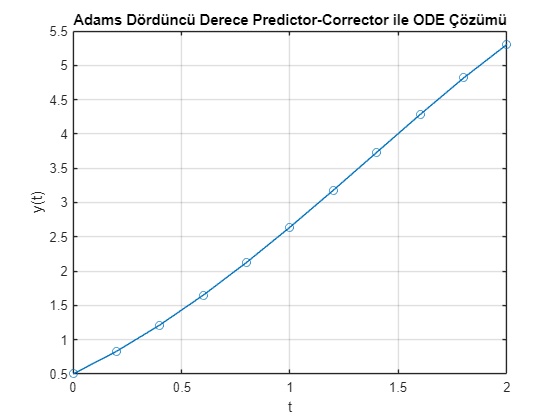


% Çözümün grafiği
plot(t, y, '-o');
title('Adams Dördüncü Derece Predictor-Corrector ile ODE Çözümü');
xlabel('t');
ylabel('y(t)');
grid on;

    `Zaman`     `Çözüm` 

    `_____`    `_______`

`       0         0.5`

`     0.2     0.82929`

`     0.4      1.2141`

`     0.6      1.6489`

`     0.8      2.1272`

`       1      2.6408`

`     1.2      3.1799`

`     1.4      3.7324`

`     1.6      4.2834`

`     1.8      4.8151`

`       2      5.3054`

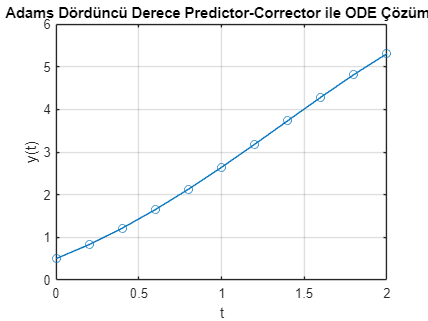

# Adams Variable Step Size Predictor Corrector

**Kodun Amacı:**Bu kod, $y^{\prime } =y+t^2 +1$ diferansiyel denklemini çözmek için Adams Variable Step Size Predictor Correcto metodunu kullanır.

Aşağıdaki satırlarda temiz bir başlangıç yapabilmek için matlab variablelar ve consol ekranı temizlenmektedir.

% 
clc;
clear;

Bu kısımda ödevde verilen $f\left(t,y\right)=y-t^2 +1$ diferansiyel denklem tanımlanmaktaır.

% Diferansiyel denklem: y' = y - t^2 + 1
f = @(t, y) y - t^2 + 1;

y_exact = @(t) (t + 1).^2 - 0.5 * exp(t); % Analitik çözüm

Başlangıç noktası bitiş noktası ve a,b,$\alpha$ , TOL ve minimum maksimum adım aralıkları belirlenir.


% Giriş değerleri
a = 0;            % Başlangıç noktası
b = 2;            % Bitiş noktası
alpha = 0.5;      % Başlangıç koşulu y(a) = alpha
TOL = 10e-5;       % Tolerans
hmax = 0.2   ;       % Maksimum adım boyutu
hmin = 0.001;      % Minimum adım boyutu

Dongüde kullanılacak değişken atamaları yapılır.

% Değişkenleri başlat
t0 = a;           % Başlangıç zamanı
w0 = alpha;       % Başlangıç çözümü
h = hmax;         % Başlangıçta maksimum adım boyutu
FLAG = 1;         % Döngüyü kontrol etmek için
LAST = 0;         % Son adımı belirlemek için
i = 1;            % Adım sayacı
sigma =0.0;         % Sigma 

Grafik çıktısı için verilerin tutulacağı arrayler oluşturuldu.

% Çözüm değerlerini saklamak için diziler
T_all = [];       % Tüm zaman değerleri
W_all = [];       % Tüm çözüm değerleri
errors = []; % Gerçek hata |y_exact - w|

Konsol çıktısının başlık yazılılarıyazdırılır.

% Başlangıç değerlerini çıktı olarak yazdır
fprintf('Adım\t   t\t       w\t       h          sigma\n');

Adım	   t	       w	       h          sigma


fprintf('%4d\t%8.4f\t%8.6f\t%8.4f\t%8.4f\n', i, t0, w0, h,sigma);

   1	  0.0000	0.500000	  0.2000	  0.0000


Vektörler oluşturulur.

% İlk üç adım için Runge-Kutta 4. derece ile hesapla
T = zeros(1, 4); % Zaman değerlerini sakla
W = zeros(1, 4); % Çözüm değerlerini sakla
T(1) = t0;
W(1) = w0;



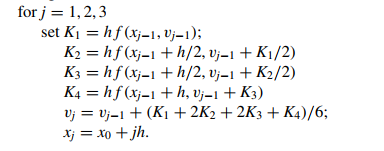

Bu adımlarda runge kutta 4. derece çözümü yapılır.


$$\begin{array}{l}
k_1 =\mathrm{hf}\left(T\left(j\right),W\left(j\right)\right)\\
k_2 =h\ldotp f\left(T\left(j\right)+\frac{h}{2},W\left(j\right)+\frac{k_1 }{2}\right)\\
k_3 =h\ldotp f\left(T\left(j\right)+\frac{h}{2},W\left(j\right)+\frac{k_2 }{2}\right)\\
k_4 =h\ldotp f\left(T\left(j\right)+h,W\left(j\right)+k_3 \right)
\end{array}$$


Yeni değer çözümü için aşağıdak formulü kullanır.


$$T\left(j+1\right)=T\left(j\right)+h$$


for j = 1:3
    % Runge-Kutta katsayılarını hesapla
    k1 = h * f(T(j), W(j));
    k2 = h * f(T(j) + h / 2, W(j) + k1 / 2);
    k3 = h * f(T(j) + h / 2, W(j) + k2 / 2);
    k4 = h * f(T(j) + h, W(j) + k3);
    
    % Bir sonraki çözüm değerini bul
    W(j + 1) = W(j) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
    T(j + 1) = T(j) + h;
    
    % Adım sayacını artır ve sonucu yazdır
    i = i + 1;
    fprintf('%4d\t%8.4f\t%8.6f\t%8.4f\t%8.4f\n', i, T(j + 1), W(j + 1), h, sigma);
end

   2	  0.2000	0.829293	  0.2000	  0.0000
   3	  0.4000	1.214076	  0.2000	  0.0000
   4	  0.6000	1.648922	  0.2000	  0.0000


Sonuçların grafik çıktısı için sonuçları bir vektörde toplandı.

% Tüm sonuçları kaydet
T_all = [T_all, T];
W_all = [W_all, W];


#### Predictor Adımı


$$\begin{array}{l}
\mathrm{WP}\;=W_4 +\frac{h}{24}\left\lbrack 55f\left(T_4 ,W_4 \right)-59f\left(T_3 ,W_3 \right)+37f\left(T_2 ,W_2 \right)-9f\left(T_1 ,W_1 \right)\right\rbrack \\
W_4 =\mathrm{şuan}\;\mathrm{ki}\;\mathrm{çözüm}\;\mathrm{değeri}\;\\
f\left(T_4 ,W_4 \right):{t_4 }^{\prime } \mathrm{te}\;\mathrm{türev}\;\mathrm{fonksiyonu}
\end{array}$$


Bu adım bir tahminde bulunur.

#### Corrector adımı 


$$W\;C=W_4 +\frac{h}{24}\left\lbrack 9f\left(T_5 ,\mathrm{WP}\right)+19f\left(T_4 ,W_4 \right)-5f\left(T_3 ,W_3 \right)+f\left(T_2 ,W_2 \right)\right\rbrack$$


$\mathrm{WP}$ Predictor adımında hesaplanan tahmin.

$\mathrm{WC}\;$Corrector adımında doğrulanmış değer

#### Hata Tahmini ($\sigma$)


$$\sigma =\frac{19\ldotp |\mathrm{WC}\;-\mathrm{WP}|}{270\ldotp h}$$


#### Faktör Hesabı 


$$q={\left(\frac{\mathrm{TOL}}{2\sigma }\right)}^{\frac{1}{4}}$$


#### Yeni Adım Boyutu

Eğer $q>4$


$$h=4h$$


değilse 


$$\begin{array}{l}
h=q\ldotp h\\

\end{array}$$


**Adım Boyutunun Sınırlandırılması**

**Maksimum Sınır**


$$h=\min \left(h,h_{\max } \right)$$


eğer  $t_4 +4h>b$


$$h=\frac{b-T_4 }{4}$$


**Minimum Sınır**

Eğer h<hmin

işlemi durdur hata mesajı yazdır.

% Predictor-Corrector döngüsünü başlat
while FLAG
    % Predictor adımı (Adams-Bashforth 4. derece)
    WP = W(4) + h / 24 * (55 * f(T(4), W(4)) - 59 * f(T(3), W(3)) + ...
                          37 * f(T(2), W(2)) - 9 * f(T(1), W(1)));

    % Corrector adımı (Adams-Moulton 4. derece)
    WC = W(4) + h / 24 * (9 * f(T(4) + h, WP) + 19 * f(T(4), W(4)) - ...
                          5 * f(T(3), W(3)) + f(T(2), W(2)));

    % Hata tahminini hesapla
    sigma = 19 * abs(WC - WP) / (270 * h);
  
    if sigma <= TOL
        % Sonucu kabul et
        t_next = T(4) + h;
        w_next = WC;

        % Sonucu yazdır
        fprintf('%4d\t%8.4f\t%8.6f\t%8.4f\t%8.4f\n', i + 1, t_next, w_next, h, sigma);

        % Değerleri güncelle
        T = [T(2:4), t_next];
        W = [W(2:4), w_next];
        i = i + 1;

        % Sonuçları sakla
        T_all = [T_all, t_next];
        W_all = [W_all, w_next];

        % Son adım kontrolü
        if LAST
            FLAG = 0;
        else
            % Adım boyutunu gerekirse ayarla
            if sigma <= 0.1 * TOL || T(4) + h > b
                q = (TOL / (2 * sigma))^(1 / 4);
                h = min(4 * h, min(q * h, hmax))

                if T(4) + 4 * h > b
                    h = (b - T(4)) / 4
                    LAST = 1;
                end
            end
        end
    else
        % Sonucu reddet ve adım boyutunu küçült
        q = (TOL / (2 * sigma))^(1 / 4);
        h = max(0.1 * h, q * h)

        if h < hmin
            % Minimum adım boyutu aşıldı, hesaplama başarısız
            FLAG = 0;
            fprintf('hmin sınırı aşıldı. Çözüm başarısız.\n');
            break;
        else
            % Daha küçük adım boyutuyla tekrar hesapla
            T = T(1:3);
            W = W(1:3);
            i = i - 3;
        end
    end
end

   5	  0.8000	2.127206	  0.2000	  0.0000
   6	  1.0000	2.640829	  0.2000	  0.0000
   7	  1.2000	3.179903	  0.2000	  0.0000
   8	  1.4000	3.732350	  0.2000	  0.0001
   9	  1.6000	4.283421	  0.2000	  0.0001
  10	  1.8000	4.815096	  0.2000	  0.0001
  11	  2.0000	5.305371	  0.2000	  0.0001


h = 0.1691

h = 5.5511e-17

  12	  2.0000	5.305371	  0.0000	  0.0000


İşlem başarılı tamamlanma mesajını yazdır. Grafik çıktısı al

% Hesaplama tamamlandı
disp('Hesaplama tamamlandı.');

Hesaplama tamamlandı.


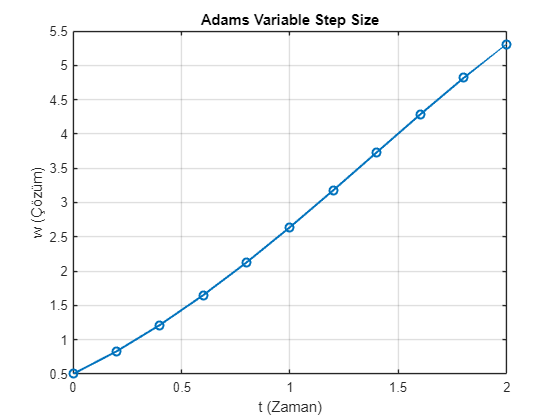


% Sonuçların Grafiği
figure;
plot(T_all, W_all, '-o', 'LineWidth', 1.5);
title('Adams Variable Step Size');
xlabel('t (Zaman)');
ylabel('w (Çözüm)');
grid on;

`  Adım	    t	            w	             h            sigma`

`   1	  0.0000	0.500000	  0.2000	  0.0000`

`   2	  0.2000	0.829293	  0.2000	  0.0000`

`   3	  0.4000	1.214076	  0.2000	  0.0000`

`   4	  0.6000	1.648922	  0.2000	  0.0000`

`   5	  0.8000	2.127206	  0.2000	  0.0000`

`   6	  1.0000	2.640829	  0.2000	  0.0000`

`   7	  1.2000	3.179903	  0.2000	  0.0000`

`   8	  1.4000	3.732350	  0.2000	  0.0001`

`   9	  1.6000	4.283421	  0.2000	  0.0001`

`  10	  1.8000	4.815096	  0.2000	  0.0001`

`  11	  2.0000	5.305371	  0.2000	  0.0001`

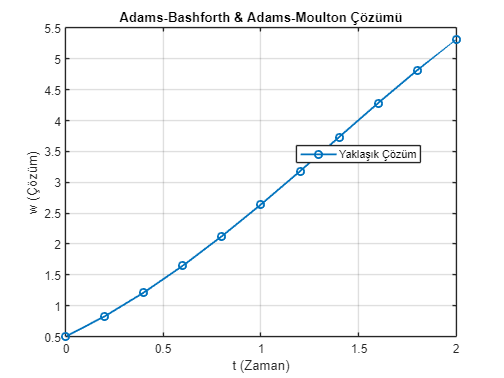

# Raleigh Ritz Metodu

Bu kod, bir radyal simetrik malzemede elastik deformasyonu ve gerilmeleri modellemek için enerji yöntemini kullanır. Kodun her bir adımı, sistemdeki yer değiştirme ve gerilme fonksiyonlarının optimize edilmesini ve sonuçların hesaplanmasını içerir.

Matlab değişkenlerini ve konsol temizleme işlemi

clc;
clear;

% Malzeme özellikleri
ElasticModulus = 207e9; % Elastisite modülü (Pa)
PoissonRatio = 0.3;     % Poisson oranı

Parçalı fonksiyonlar için sembolik değişkenlerin oluşturulması.

% Parçalı fonksiyonun tanımı için sembolik değişkenler
syms Radius Coef0 Coef1 Coef2 Coef3 Coef4



Parçalı bir yer değiştirme fonksiyonu u(r)u(r)u(r), radyal bölgeler için şu şekilde tanımlanmıştır:


$$u\left(r\right)\;$$
       
$$\begin{array}{l}
C_0 +C_1 r\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;0\ldotp 25\le r\;\le 0\ldotp 333\\
C_0 +0\ldotp 333C_1 -0\ldotp 333C_2 +C_2 r\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;0\ldotp 333\le r\le 0\ldotp 4167\\
C_0 +0\ldotp 333C_1 -0\ldotp 333C_2 +0\ldotp 4167C_2 -0\ldotp 4167C_4 +C_4 r\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;0\ldotp 4167\le r\le 0\ldotp 5
\end{array}$$


DisplacementFunction = piecewise(...
    0.25 <= Radius & Radius <= 0.33, Coef0 + Coef1*Radius, ...
    0.33 < Radius & Radius <= 0.4167, Coef0 + 0.33*Coef1 - 0.33*Coef2 + Coef2*Radius, ...
    0.4167 < Radius & Radius <= 0.5, Coef0 + 0.33*Coef1 - 0.33*Coef2 + 0.4167*Coef2 - 0.4167*Coef4 + Coef4*Radius);

Malzemenin elastik enerjisi üç ana bileşene ayrılmıştır:

### **Elastik deformasyon enerjisi:**


$$I_1 =\int_{0\ldotp 25}^{0\ldotp 5} {\left(\frac{\mathrm{du}}{\mathrm{dr}}\right)}^2 r\;\mathrm{dr}$$


Integral1 = int((DisplacementDerivative)^2 * Radius, Radius, 0.25, 0.5);

Unrecognized function or variable 'DisplacementDerivative'.

### Poisson etkisi enerjisi:


$$I_1 =\int_{0\ldotp 25}^{0\ldotp 5} {\left(\frac{\mathrm{du}}{\mathrm{dr}}\right)} u\;\mathrm{dr}$$


Integral2 = int(DisplacementDerivative * DisplacementFunction, Radius, 0.25, 0.5);
Integral2 = 2 * PoissonRatio * Integral2; % Poisson oranı ile çarpılır.

### Radyal gerilme enerjisi:


$$I_1 =\int_{0\ldotp 25}^{0\ldotp 5} \frac{u^2 }{r}\;\mathrm{dr}$$


Integral3 = int(DisplacementFunction^2 / Radius, Radius, 0.25, 0.5);

Bu enerji bileşenleri, elastisite modülü $E$ ve Poisson oranı $v$ ile ağırlıklandırılarak toplam enerji fonksiyonunu oluşturur:


$$\i =\frac{E}{2\left(1-v^2 \right)}\left(I_1 +I_2 +I_3 \right)$$


% Elastisite modülü ve Poisson oranı kullanılarak enerji bileşenleri hesaplanır.
Integral1 = ElasticModulus / (2 * (1 - PoissonRatio^2)) * Integral1;
Integral2 = ElasticModulus / (2 * (1 - PoissonRatio^2)) * Integral2;
Integral3 = ElasticModulus / (2 * (1 - PoissonRatio^2)) * Integral3;

TotalEnergy = Integral1 + Integral2 + Integral3;

### **Kenar Koşulları ve Toplam Enerji**

Kenar koşulları enerjiyi etkiler:


$$\mathrm{BC}=0\ldotp 25\cdot \left(200\times {10}^6 \right)\cdot \left(C_0 +0\ldotp 25C_1 \right)$$


BoundaryCondition = 0.25 * (200e6) * (Coef0 + Coef1 * 0.25);
TotalEnergy = TotalEnergy - BoundaryCondition;

Toplam enerji fonksiyonu şu şekilde güncellenir:


$$I_{\mathrm{total}} =2\pi \cdot 0\ldotp 25\cdot \left(I-\mathrm{BC}\right)$$


TotalEnergy = 2 * pi * 0.25 * TotalEnergy;

### Enerji Minimizasyonu

Enerji fonksiyonu sabitler açısından minimize edilir:


$$\;\frac{\partial I_{\mathrm{total}} }{\partial C_i }=0\left(i=0,1,2,4\right)$$


PartialDerivatives = [diff(TotalEnergy, Coef0); diff(TotalEnergy, Coef1); ...
                      diff(TotalEnergy, Coef2); diff(TotalEnergy, Coef4)];

% (6) Denklem sistemi oluşturuluyor
% Enerji minimizasyonundan elde edilen denklemler çözülür.
Equations = PartialDerivatives == 0;

% (7) Sabitlerin çözümü
% Sabitlerin analitik çözümü bulunur.
Solutions = solve(Equations, [Coef0, Coef1, Coef2, Coef4]);

% Çözümleri sayısal değerlere dönüştürme
Constants = structfun(@vpa, Solutions, 'UniformOutput', false);

### Optimize Edilmiş Fonksiyonlar

Yer değiştirme fonksiyonu ve türevleri sabitler ile güncellenir:

**Yer değiştirme fonksiyonu:**


$$u_{\mathrm{opt}} \left(r\right)$$


OptimizedDisplacement = piecewise(...
    0.25 <= Radius & Radius <= 0.33, Constants.Coef0 + Constants.Coef1*Radius, ...
    0.33 < Radius & Radius <= 0.4167, Constants.Coef0 + 0.33*Constants.Coef1 - 0.33*Constants.Coef2 + Constants.Coef2*Radius, ...
    0.4167 < Radius & Radius <= 0.5, Constants.Coef0 + 0.33*Constants.Coef1 - 0.33*Constants.Coef2 + 0.4167*Constants.Coef2 - 0.4167*Constants.Coef4 + Constants.Coef4*Radius);


**Türev:**


$$\frac{{\mathrm{du}}_{\mathrm{opt}} }{\mathrm{dr}}$$


OptimizedDisplacementDerivative = diff(OptimizedDisplacement, Radius);

### Gerilme Hesaplamaları

Optimize edilmiş türevler kullanılarak radyal ve çevresel gerilmeler hesaplanır:

**Radyal gerilme**


$$\sigma_r =\frac{E}{1-v^2 }\left(\frac{{\mathrm{du}}_{\mathrm{opt}} }{\mathrm{dr}}+v\frac{u_{\mathrm{opt}} }{r}\right)$$


RadiusValues = [0.250001, 0.375, 0.4999999];
RadialStressValues = double(subs(RadialStress, Radius, RadiusValues));

**Çevresel gerilme**


$$\sigma_{\theta } =\frac{E}{1-v^2 }\left(v\frac{{\mathrm{du}}_{\mathrm{opt}} }{\mathrm{dr}}+\frac{u_{\mathrm{opt}} }{r}\right)$$


CircumferentialStress = (ElasticModulus / (1 - PoissonRatio^2)) * (OptimizedDisplacementDerivative * PoissonRatio + OptimizedDisplacement / Radius);


**Displacement Hesaplaması**

DisplacementValues = double(subs(OptimizedDisplacement, Radius, RadiusValues));

**Dataların Çıktı Alınması**

disp('Constants :');
disp(Constants);
disp('Radial Stress (Pa):');
disp(RadialStressValues);
disp('Circumferential Stress (Pa):');
disp(CircumferentialStressValues);
disp('Displacement Values (m):');
disp(DisplacementValues);